# Constants


Ma=[0.6:0.1:8];
Gc=1.4

Gc = 1.4000

Gh=1.333

Gh = 1.3330

R=1715  %lbft/slugR

R = 1715

Cpc=(Gc*R)/(Gc-1);
Cph=(Gh*R)/(Gh-1);
OPR=12

OPR = 12

Etc=0.88;
Pbc=0.03;%Pressure loss combustor
T04=3475;%R
Etb=0.99; %Efficiency of burner
QR=4.83*10^8; %ftlb/slug
Etm=0.99; % Mechanical Efficiency
Ett=0.91; % Turbine Efficiency
Etn=0.95; % Nozzle Efficiency
Aa=2.25; % Area of inlet (ft^2)
Etr = double.empty(0,75);
P0a=double.empty(0,75);
T0a=double.empty(0,75);
Va=double.empty(0,75);
TSFC=double.empty(0,75);
TSFC2=double.empty(0,75);
TSFC3=double.empty(0,75);




for i=1:length(Ma)
%%%% Etha(r) %%%%%
    if Ma(i)<=1
        Etr(i)=1;
    elseif Ma(i)>1 && Ma(i)<= 5
        Etr(i)=1-0.075*(Ma(i)-1)^1.35;
    else 
        Etr(i)=800/(Ma(i)^4+935);
    end   



## At Atmosphere


    Pa=(0.2715*(2116.2)+0.2592*(2116.2))/2;%lbf/ft^2
    Ta=(0.7803*(518.69)+0.7735*(518.69))/2;%R
    P0a(i)=Pa.*(1+(Gc-1)./2.*Ma(i).^2).^(Gc./(Gc-1));%lbf/ft^2
    T0a(i)=Ta*(1+(Gc-1)/2*Ma(i)^2);%lbf/ft^2
    Va(i)=Ma(i)*sqrt(Gc*R*Ta); % ft/sec

## At Station 1


    P01=P0a;
    T01=T0a;



## At Station 2

    T02=T01;
    P02=Etr.*P01;



## At Station 3

    P03=OPR*P02;
    T03=T02*(1+((1/Etc)*((OPR^((Gc-1)/Gc)-1))));


## At Station 4

P04=P03*(1-Pbc);
T04=T04;
f=(((Cph.*T04)./(Cpc*T03)-1)./((Etb.*QR)./(Cpc.*T03)-(Cph.*T04)./(Cpc.*T03)));


## At Station 5

T05=T04-(Cpc/(Cph*Etm))*(T03-T02);
T05s= T04-(1/Ett)*(T04-T05);
P05=P04.*(1-(1./Ett).*(1-(T05./T04))).^(Gh./(Gh-1));
   

## At Station 6

1. Nozzle-1(Choked)

M6=1;
CPR=1./(1-(1./Etn).*((Gh-1)./(Gh+1)).^(Gh./(Gh-1)));% Critical Pressure Ratio
T06=T05; % Adiabatic Nozzle
T6=T06/(1+(Gh-1)/2*M6);
V6=M6*sqrt(Gh*R*T6);% ft/sec
wa=Pa/(R*Ta)*Va*Aa;
A6=(wa.*(1+f))./((P05.*sqrt(Gh)./sqrt(R.*T05)).*(2./(Gh+1)).^((Gh+1)./(2.*(Gh-1)))); % ft^2
TPR=(1./CPR).*(P05./P04).*(1-Pbc).*OPR.*Etr.*(P0a./Pa);
TA=A6/Aa;
T=(1+f).*V6-Va+((R.*Ta)./Va).*((TPR.*TA)-1);%lbfs/slug
TSFC(i)=f/T;% slug/lbfs

2. Nozzle-2 (Area =0.55ft^2)

A62=0.55;
TA2=A62/Aa;
PR2=P05/Pa ;%% Pressure Ratio
Wchk=((A62*P05*sqrt(Gh))/(sqrt(R*T05)))*(2/(Gh+1))^((Gh+1)/(2*(Gh-1)));
T2=((Wchk./wa).*V6)-Va+((R.*Ta)./Va).*((TPR.*TA2)-1);%lbfs/slug
TSFC2(i)=f/T2;% slug/lbfs

3. Nozzle-3 (Area=0.75ft^2)

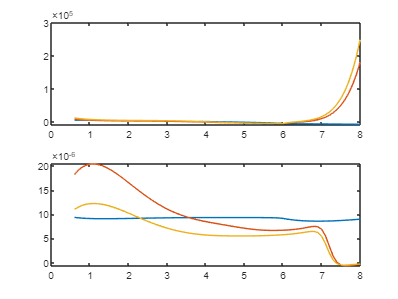


A63=0.75;
TA3=A63/Aa;
PR2=P05/Pa; %% Pressure Ratio
Wchk3=((A63*P05*sqrt(Gh))/(sqrt(R*T05)))*(2/(Gh+1))^((Gh+1)/(2*(Gh-1)));
T3=((Wchk3./wa).*V6)-Va+((R.*Ta)./Va).*((TPR.*TA3)-1);%lbfs/slug
TSFC3(i)=f/T3;% slug/lbfs

end

subplot(2,1,1)
plot(Ma,T,Ma,T2,Ma,T3)

subplot(2,1,2)
plot(Ma,TSFC,Ma,TSFC2,Ma,TSFC3)
